# **OOK Transmitter-Receiver System**

**By**:Rahul Gulia

**Instructor**: Dr. Miguel Bazdresch

% Clear variables
clearvars;
clc;
clear all;
close all;


## 2.1: Input variables

T=1;    % pulse interval or time period, and Symbol period = 1/T
Es = 1;   % Average energy/symbol in the OOK constellation
Eb = Es;
fc = 10;    % Carrier frequency in Hz
phi = 0;
% phi=pi/4;
beta = 0.5 ;   % SRRC pulse excess bandwidth
k=1;    %

## 2.2: Assuming Sampling frequency

fs = 100;    % Assuming sampling frequency
ts = 1/fs;  % Sampling period


## 2.3: Generating SRRC pulse shape

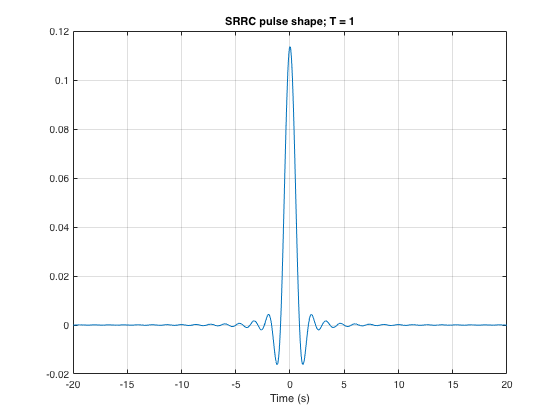

[p, tt] = srrcpulse(beta, T, ts, 20);
plot(tt,p);
grid on;
% ylim([-0.08,0.4]);
title('SRRC pulse shape; T = 1'); xlabel('Time (s)');

## 2.4: Calculating OOK constellation, and baseband OOK signal

N_tmp = 10000;
N = randi(2,1,N_tmp);    % generating 100 random symbols
d = sqrt(2*Es);
C = [0 d];      % Generating the constellation
syms = C(N);   % Generating N symbols on the constellation
syms_up = upsample(syms, fs*T);

bb = conv(p, syms_up);  % baseband OOK signal

## 2.5: Generating carrier frequency and phase

t1 = 0:ts:ts*(length(bb)-1);
carrier = cos(2*pi*fc*t1 + phi);

## 2.6: Generating passband OOK signal

ook = bb.*carrier;


## 2.7-2.8: Plotting the spectrum

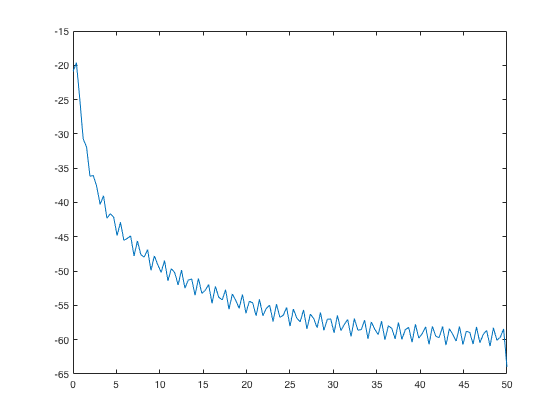

seglength = 100;
[pp, ff] = pwelch(bb, rectwin(seglength),0,256,fs,'psd');
plot(ff,10*log10(pp))

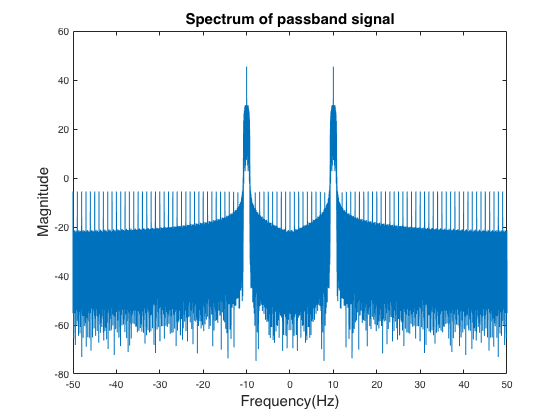


[m, f] = getspectrum(ook, ts,1);

figure
plot(f,10*log10(m))
xlabel("Frequency(Hz)", 'FontSize',15);
ylabel("Magnitude", 'FontSize',15);
title("Spectrum of passband signal", 'FontSize',15);

## 3.1: Non-coherent quadrature receiver

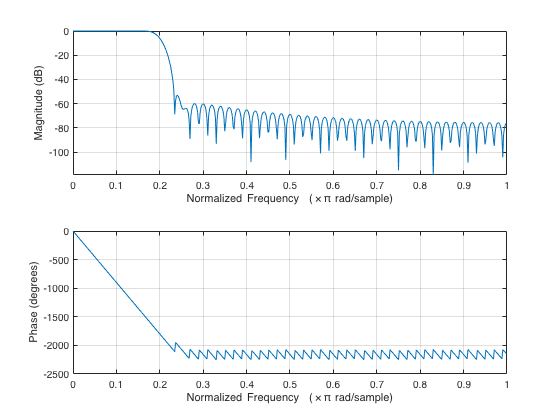

% In-phase part
Spb_i = ook.*cos(2*pi*fc*t1);
fn = fs/2;  % Nyquist frequency
LPF = fir1(100, 10/fn);
freqz(LPF)


% S_i = filter(LPF,1,Spb_i);
S_i = conv(Spb_i,LPF);

r1 = S_i;
mf1 = conv(p, r1);
r_i = mf1;  %In-phase signals


% Quadrature-phase part
Spb_q = ook.*sin(2*pi*fc*t1);

% S_q = filter(LPF,1,Spb_q);
S_q = conv(Spb_q,LPF);

r2 = S_q;
mf2 = conv(p, r2);
r_q = mf2;  %In-phase signals


## Eye diagrams

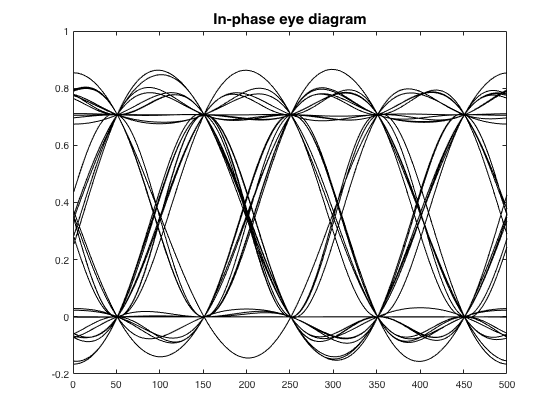

eye_I = geteyed(mf1,100,5,20,200);
plot(eye_I,'k');
% ylim([-1*10^-5 1*10^-5])
title('In-phase eye diagram', 'FontSize',15);

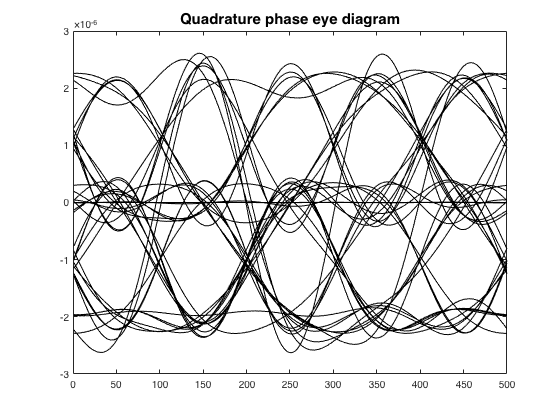


eye_Q = geteyed(mf2,100,5,20,200);
plot(eye_Q,'k');
% ylim([-0.4*10^-5 0.5*10^-5])
title('Quadrature phase eye diagram', 'FontSize',15);

## 3.2: Sampling the Matched Filter output at correct times

Rxd_symbol = sqrt((r_i*cos(phi)).^2 + (r_q*sin(phi)).^2);

% figure
% plot(Rxd_symbol)
% xlabel('Amplitude'), ylabel('time'), title('Received symbols')
% grid on
% grid minor

t_ini = 4070;

## 3.3: Detecting the transmitted symbols

Rx_matched = Rxd_symbol(t_ini:100:end);

Rx1 = [];
for idx1 = 1:length(Rx_matched)
    if Rx_matched(idx1)<0.4
        tmp1 = 0;
    elseif Rx_matched(idx1)>0.4
        tmp1 = d;
    end
    Rx1 = [Rx1 tmp1];
end
Rx1 = Rx1(1:N_tmp);

% figure
% plot(syms,'k','LineWidth',1)
% hold on
% plot(Rx1,'g--','LineWidth',1.5)
% xlabel('Number of bits transmitted'),ylabel('Amplitude');
% legend('Transmitted data', 'Received data');
% title('Transmitted and received data for OOK system.');

## 3.4: Checking the received bits

fprintf('The error in the system is: ')

The error in the system is: 

Error = sum(syms~=Rx1)

Error = 0

The required noise variance is: 

Noby2 = 0.1000

The expected error rate is: 

Err_expected = 0.0410

The error in the system is: 

Error = 379

Error_rate = 0.0379

Err_expected = 0.0410

## 4.1: Error rates

SNR_vec = 9:15;

for idx1 = 1:length(SNR_vec)
    SNR_tmp = SNR_vec(idx1);
    SNR_lin_tmp = 10^(SNR_tmp/10);

    No_var = (Eb)/SNR_lin_tmp;

    Err_expected_tmp(idx1) = 0.5*exp(-(SNR_lin_tmp/4));

    % Creating the noise with variance No/2 for the Received symbols
    n_i_tmp = randn(size(r_i))*(No_var);
    n_q_tmp = randn(size(r_q))*(No_var);
    
    % Adding the above calculated noise to the Received symbols
    r_i_noisy_tmp = r_i + n_i_tmp;
    r_q_noisy_tmp = r_q + n_q_tmp;
    
    
    Rxd_symbol_noisy_tmp = sqrt((r_i_noisy_tmp*cos(phi)).^2 + (r_q_noisy_tmp*sin(phi)).^2);

    t_ini_noisy_tmp = 4076;
    Rx_matched_noisy_tmp = Rxd_symbol_noisy_tmp(t_ini_noisy_tmp:100:end);

    Rx1_noisy_tmp = [];
    for idx2 = 1:length(Rx_matched_noisy_tmp)
        if Rx_matched_noisy_tmp(idx2)<0.4
            tmp2 = 0;
        elseif Rx_matched_noisy_tmp(idx2)>0.4
            tmp2 = d;
        end
        Rx1_noisy_tmp = [Rx1_noisy_tmp tmp2];
    end
    Rx1_noisy_tmp = Rx1_noisy_tmp(1:N_tmp);

    Error_tmp = sum(syms~=Rx1_noisy_tmp);
    Error_rate_tmp(idx1) = Error_tmp/N_tmp;

end


## 4.2: Plots

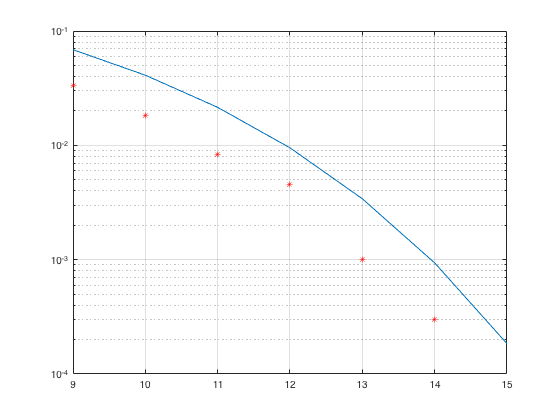


figure
semilogy(SNR_vec,Err_expected_tmp)
hold on
semilogy(SNR_vec, Error_rate_tmp,'r*')
grid on